% clear variables
clear

startN = 2;
endN = 40;


% define region
startX = 0;
endX = 10;


deviations = zeros(1, endN - startN + 1);


for n = startN:endN
    
    X = linspace(startX, endX, n);
    %X = chebyshevRoots(startX, endX, n);

    Y = sin(X);

    %P = lagrange(X, Y);
    P = newton(X, Y);
    %P = polyfit(X, Y, length(X) - 1);

    miniStepX = 0.001;
    miniX = startX:miniStepX:endX;
    
    F = sin(miniX);
    P = polyval(P, miniX);
    
    deviations(n-startN+1) = maxDeviation(miniX, F, P);

    fprintf("n = %d, deviation = %.20f\n", n, deviations(n-startN+1))
end

n = 2, deviation = 1.42875325729901825333
n = 3, deviation = 1.89536126750083067094
n = 4, deviation = 1.32688571970547264378
n = 5, deviation = 1.00725478646613031408
n = 6, deviation = 0.63003729813039022201
n = 7, deviation = 0.26627329701115742822
n = 8, deviation = 0.14839301479065980516
n = 9, deviation = 0.04164197273873684879
n = 10, deviation = 0.02103033230072431925
n = 11, deviation = 0.00434778917592060221
n = 12, deviation = 0.00201425364826762765
n = 13, deviation = 0.00032625614173353856
n = 14, deviation = 0.00013988331103292895
n = 15, deviation = 0.00001849070834419875
n = 16, deviation = 0.00000738690905047190
n = 17, deviation = 0.00000082049130639694
n = 18, deviation = 0.00000030707821768727
n = 19, deviation = 0.00000002929865128287
n = 20, deviation = 0.00000001031915716765
n = 21, deviation = 0.00000000086012341693
n = 22, deviation = 0.00000000028677281383
n = 23, deviation = 0.00000000002005551281
n = 24, deviation = 0.00000000000974997860
n = 25, deviation =

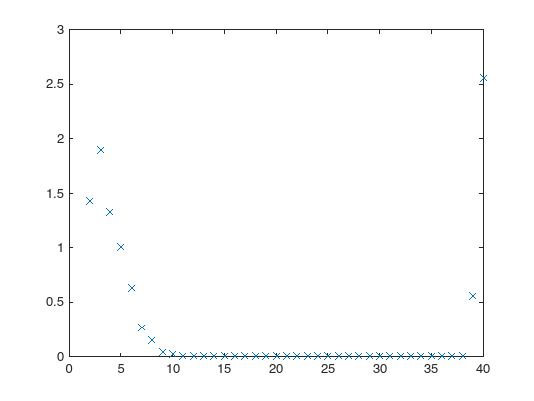



N = startN:endN;

plot(N, deviations, "x")